% Pad Z with NaN values to match the size of X and Y
[X, Y] = meshgrid(lon_grid, lat_grid);
slice_index = 1;  % Choose the slice index
Z = squeeze(grid_mat(:,:,slice_index));
Z_padded = NaN(size(X));
Z_padded(1:size(Z, 1), 1:size(Z, 2)) = Z;

% Create the plot with contours
figure;
contourf(X, Y, Z_padded);

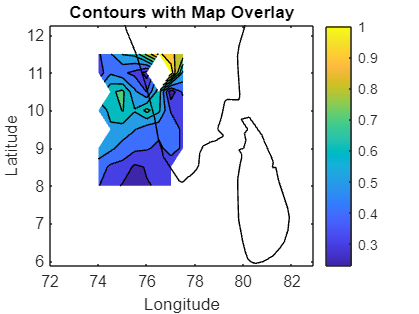

colorbar;
hold on;

% Plot the map
geoshow('landareas.shp', 'FaceColor','none');

% Adjust the axes labels
xlabel('Longitude');
ylabel('Latitude');
title('Contours with Map Overlay');